### **Problems 1-4.**

We first have to create a matrix from this list, which is done by looping through the list and then adding a 1 at wherever the edge list numbers are. after to see number of friends we then look at each row or column and add all of the ones together.

load("edges0.mat", "-ascii");
maxnum = max(edges0(:,1));
matrix = zeros(maxnum); %initialize matrices first
edgessize = size(edges0,1);

for i = 1:edgessize
    matrix(edges0(i,1),edges0(i,2)) = 1;
end

numfriends = zeros(maxnum,2); %initialize matrices first
numfriends(:,1) = 1:maxnum;
numfriends(:,2) = sum(matrix);

**Problem 1.**

Problem 1 just involves sorting the rows based on the number of friends in descending order usings the 'sortrows' function. 

%flipped the matrix to make it easier to read, top value is person, bottom
%is number of friends
P1 = sortrows(numfriends,2,'descend')' 

P1 =     56    67   271   322    25    26    21   252   277   122   119   239     9   200   203   315   304    98   188   199   285   170   272    40   186   142   280   332   172   113   213   323   325   169   261   109   236   313   118   291    82   342   104    13    53   211   329   128   141   224
    77    75    72    71    68    67    64    64    64    62    61    58    56    56    56    55    54    48    47    46    46    45    44    43    43    42    42    42    40    39    38    38    38    37    37    36    36    36    35    35    33    33    31    30    30    29    29    27    27    27


**Problem 2.**

Problem 2 just involves doing the same thing but sorting the rows in ascending order.

P2 = sortrows(numfriends,2,'ascend')'

P2 =     11    12    15    18    37    43    74   114   209   210   215   287   292   335    33    34    35    42    47    52    70    90   138   145   153   154   160   183   198   205   216   233   234   241   244   255   256   267   279   282   286   305   316    61    71    76    81    97   107   112
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2


**Problem 3.**

this is just the list that was created from adding all the rows up from the adjacency matrix.

P3 = numfriends'

P3 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
    16     9    16     9    12     5    19     7    56     9     0     0    30    14     0     8    12     0    15    14    64    10    16    15    68    67     4    12    12    16    22     5     1     1     1    10     0     8    14    43    23     1     0     5    11     4     1    21     3    10


**Problem 4.** 

Problem 4 is just a simple histogram of the number of friends that each person has. 

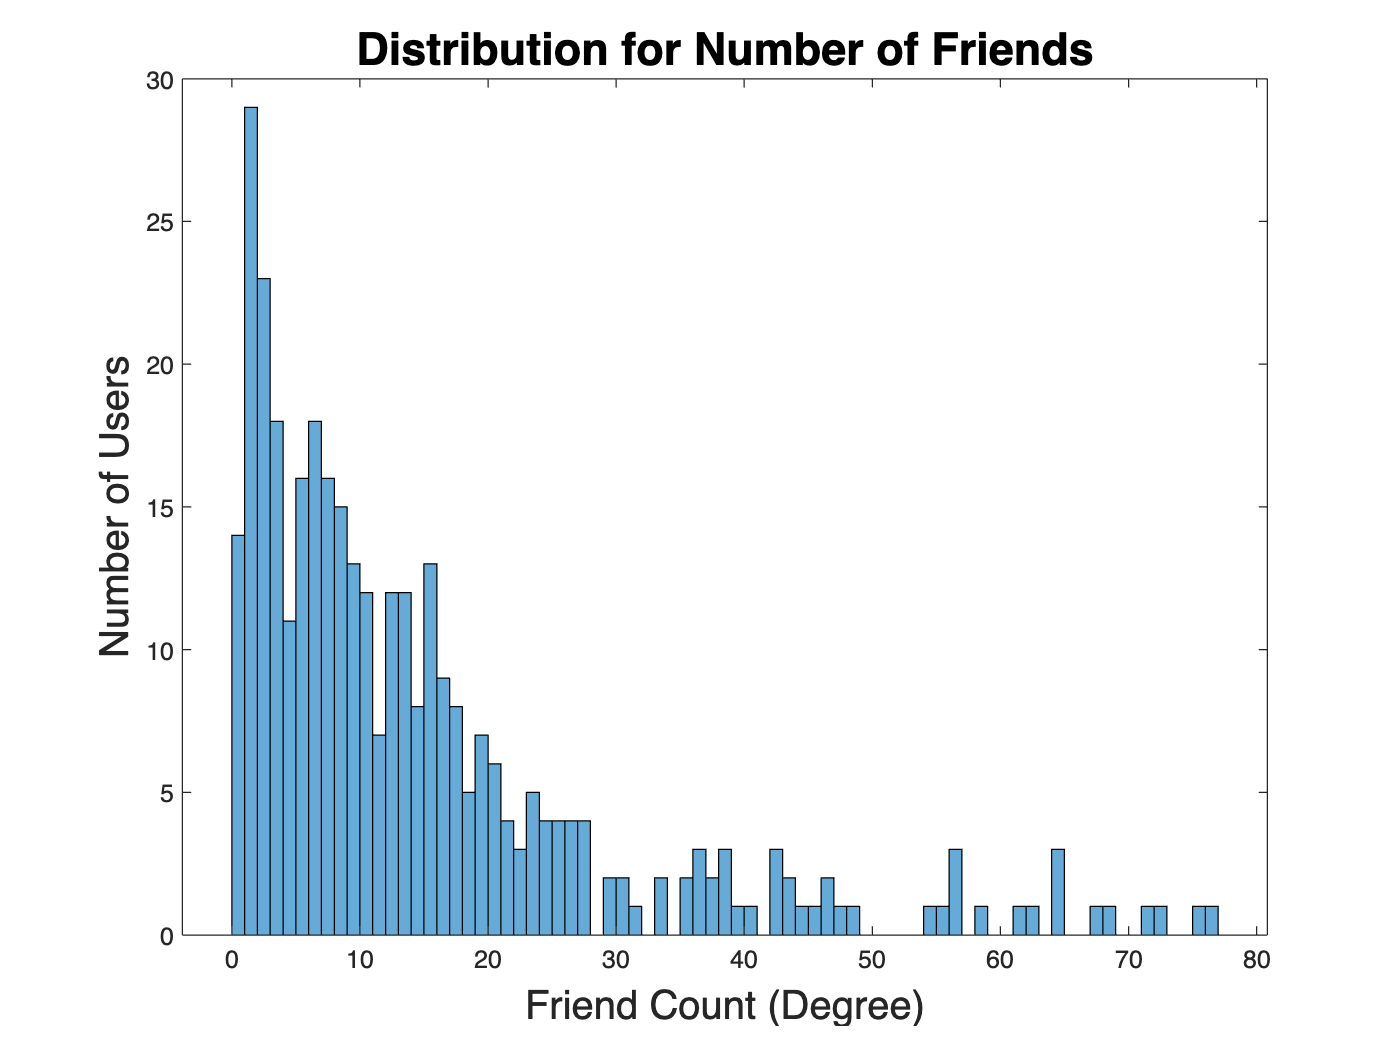

P4 = histogram(P3(2,:),maxnum+1,'BinWidth',1);
xlabel('Friend Count (Degree)','FontSize',16)
ylabel('Number of Users','FontSize',16)
title('Distribution for Number of Friends','FontSize',18)

**Problem 5. **

First find the largest supgroup of nodes (I used conncomp an checked that bin 1 was the larges group, after I made a matrix for path length from I to J and passed it through a loop to find the shortest between each node and all others. after I looped through the shortest paths and counted the number of times that each person appeared to determine their centrality.

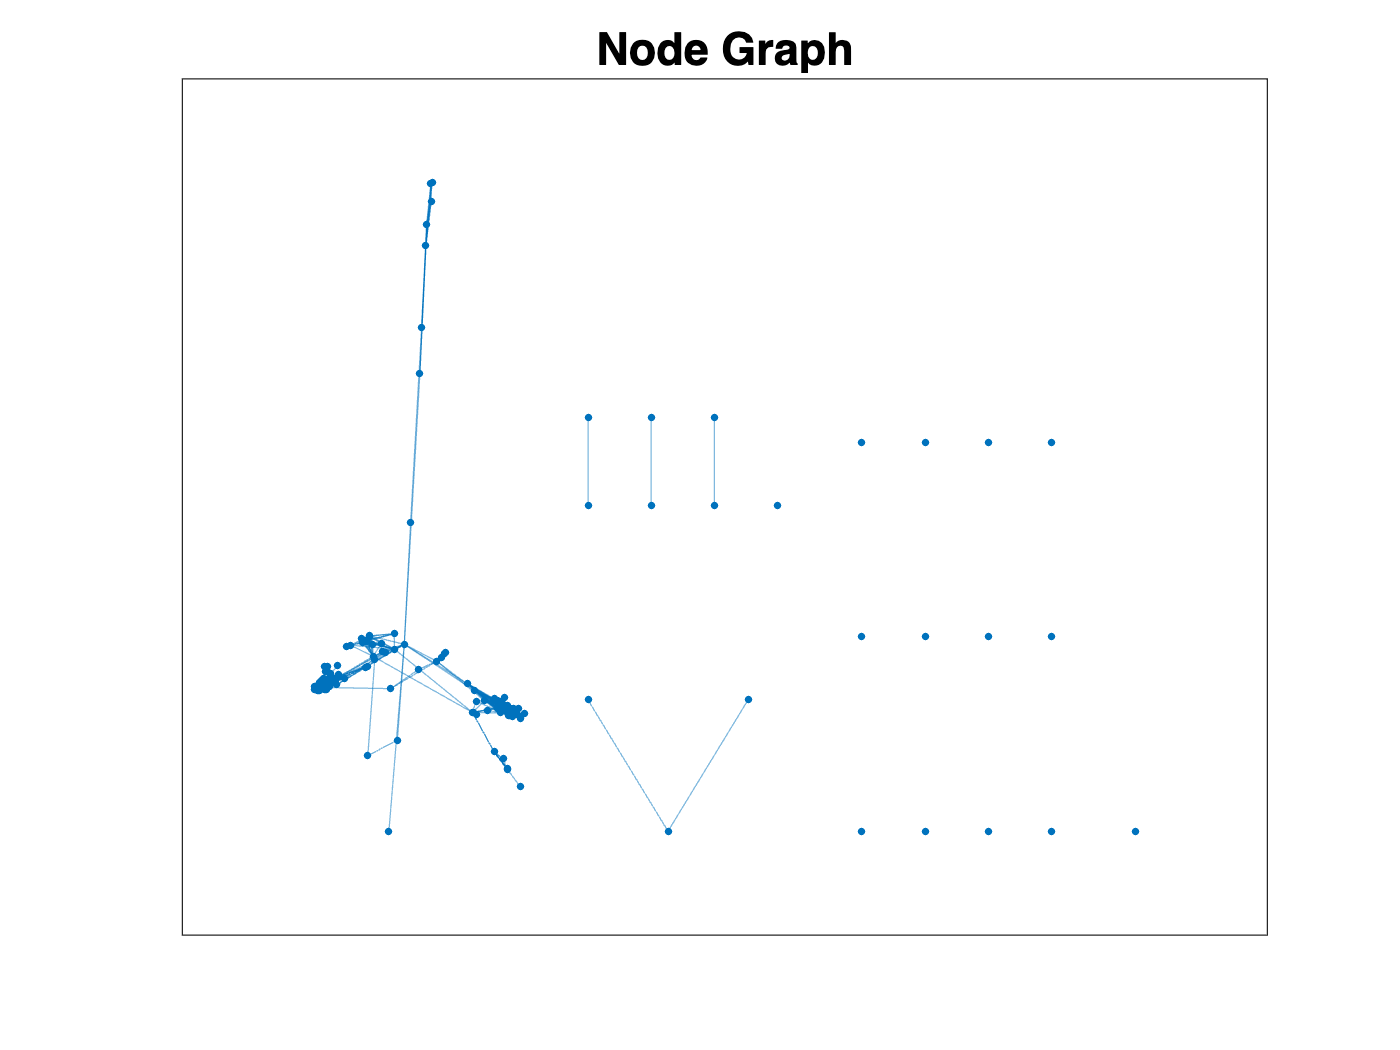

g = graph(matrix);
plot(g)
title('Node Graph','FontSize',18)

bins = conncomp(g);
pathlength = zeros(maxnum);
%initializing 
SPathCentrality = zeros(maxnum,2);
SPathCentrality(:,1) = 1:maxnum;


for i = 1:maxnum
    %not calculating the ones that arent necessary/in another bin
    if (bins(i) == 1) 

        for j = 1:maxnum

            if (bins(j) == 1) 

                if (i ~= j) %we want to exclude going through itself

                    [path, pathlength(i,j)] = shortestpath(g,i,j); %just shortest path function

                    %using the shortest path, we find the number of times
                    %each node is added for centrality
                    for k = 2:(size(path,2)-1)
                        SPathCentrality(path(k),2) = SPathCentrality(path(k),2)+1;
                    end
               end
            end
        end
    else 
        %these node will have -1 as they are not in the right group
       SPathCentrality(i,2) = -1;
    end
end

Problem 5A.

For problem 5A, the max function shows that the pairs of nodes with the largest shortest path between them are [241,198] and [255,198]

%find largest path length, in this case it is 11
M = max(pathlength(:));
[row,col] = find(pathlength == M)

row =    241
   255
   198
   198


col =    198
   198
   241
   255


**Problem 5B.** 

One measure of node importance in a network can be defined by considering how many shortest paths between other nodes a given node is on. Define the “shortest path centrality” of person i as the number of shortest paths between other nodes, j and k, which pass through i. Compute the shortest path centrality for all people in this network. first make a list of all of the people, then find the shortest path between all. add 1 to evey person that shows up in the shortest path.	

P5B = SPathCentrality'

P5B =            1           2           3           4           5           6           7           8           9          10          11          12          13          14          15          16          17          18          19          20          21          22          23          24          25          26          27          28          29          30          31          32          33          34          35          36          37          38          39          40          41          42          43          44          45          46          47          48          49          50
        1530         233         900        3780        1344           4         948        1914        7836           0          -1          -1        2027         289          -1         124        2526          -1       21033         148       10126         703       13634          94       13932        1527           8           8         660         215        2520           0         

Problem 5C. 

for Problem 5C, we need to find where each person was not used in a shortest path so we can determine that the following are boundary nodes.

P5C = SPathCentrality(SPathCentrality(:,2) == 0)'

P5C =     10    32    34    35    44    46    47    52    60    63    66    69    70    71    75    76    78    79    83    86    91    95   102   105   107   110   112   123   125   129   131   135   138   139   140   142   147   150   151   153   154   155   157   160   162   164   165   167   174   176


Problem 5D.

for problem 5D, we just need to find the person that appeared in the most shortest paths to determine who is most central to the network. from this we can see that 

P5D = [find(SPathCentrality(:,2) == max(SPathCentrality(:,2))) max(SPathCentrality(:,2))]

P5D =          277       27969


**Problem 6A.**

For Problem 6A, we need to test all 3 node combinations to see if they are connected to each other, and if they are then add them to the list of 3-cliques.

P6A = [];

%we iterate to maxnum-2 so there are two other nodes to test against
for i = 1:maxnum-2 
    for j = i+1:maxnum-1
        %we test here if there is a connection between i and j if not we
        %dont have to continue
        if matrix(i, j) == 1 

            for k = j+1:maxnum
                if matrix(i, k) == 1 && matrix(j, k) == 1
                    P6A = [P6A; i j k]; %add new clique to list
                end
            end
        end
    end
end
P6A

P6A =      1    48    53
     1    48    54
     1    48    73
     1    48    88
     1    48   119
     1    48   126
     1    48   299
     1    48   322
     1    53    54
     1    53    88


**Problem 6B.**

For problem 6B one method of solving it could be to start on each node, and then testing to see the largest clique that can be made from this node. The largest clique is found by seing if each neighbor of a node fits in with all other nodes in the clique, and it if does then it adds it to the clique. Because this isnt a brute force alogrithm this could possibly not be the largest/only answer, but this problem is an exponentially increasing problem because a brute force would require checking every sub set to see if they made a clique.

largestClique = [];

%going through each node in the network
for node = 1:maxnum

    %take a node and add it to the clique, and then keep track of all of
    %its neighbors
    neighbors = find(matrix(node, :));
    clique = node;
    
    while true

        %the extend variable keeps track of whether or not the clique has
        %been added to
        extend = false;
        newNeighbors = [];
        
        %iterate through all neighbors
        for i = 1:length(neighbors)
            neighbor = neighbors(i);

            %tests th enew neighbor against all others in the clique
            if all(matrix(neighbor, clique))
                %if true adds new neighbor to the clique
                clique = [clique neighbor];
                extend = true; %extended clique and finds new neighbors
                newNeighbors = [newNeighbors setdiff(neighbors, neighbor)];
            end
        end
        
        if ~extend || isempty(newNeighbors)
            break;
        end
        
        neighbors = newNeighbors;
    end
    
    if length(clique) > length(largestClique)
        largestClique = clique;
    end
end

P6B = largestClique

P6B =    104    21    25    26    56    67    98   122   186   200   203   239   271   277   325
